# Machine Learning for Statistical Arbitrage III: Training, Tuning, and Prediction

This example uses Bayesian optimization to tune hyperparameters in the algorithmic trading model, supervised by the end-of-day return. It is part of a series of related examples on machine learning for statistical arbitrage (see [docid:finance_doccenter#mw_0f023f59-cdcc-4a84-81b4-b22e9c5160e3](docid:finance_doccenter#mw_0f023f59-cdcc-4a84-81b4-b22e9c5160e3)).

Load `LOBVars.mat`, the preprocessed LOB data set of the NASDAQ security INTC.

load LOBVars

The data set contains the following information for each order: the arrival time `t` (seconds from midnight), level 1 asking price `MOAsk`, level 1 bidding price `MOBid`, midprice `S`, and imbalance index `I`.

This example includes several supporting functions. To view them, open the example, and then expand the `LOBSupportingFiles` folder in the **Current Folder** pane.

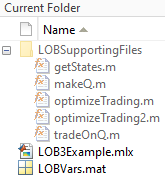

Access the files by adding them to the search path.

addpath("LOBSupportingFiles")

## Trading Strategy

The trading matrix `Q` contains probabilities of future price movements, given current and previous states `rho` of the limit order book (LOB) imbalance index `I` and the latest observed direction in prices `DS`. 

View the supporting function `tradeOnQ.m`, which implements a simple trading strategy based on the pattern in `Q`. 

The algorithm uses predictions from `Q` to make decisions about trading at each tick. It illustrates the general mechanism of any optimized machine learning algorithm.

This strategy seeks to profit from expected price changes using market orders (best offer at the touch) of a single share at each tick, if an arbitrage opportunity arises. The strategy can be scaled up to larger trading volumes. Using the conditional probabilities obtained from `Q`, the `tradeOnQ` function takes one of these actions:

- Executes a buy if the probability of an upward forward price change is greater than 0.5.

- Executes a sell if the probability of an downward forward price change is greater than 0.5.

At the end of the trading day, the function liquidates the position at the touch.

The strategy requires `Data` with tick times `t` and the corresponding market order bid and ask prices `MOBid` and `MOAsk`, respectively. In real-time trading, data is provided by the exchange. This example evaluates the strategy by dividing the historical sample into *training* (calibration) and *validation* subsamples. The validation subsample serves as a proxy for real-time trading data. The strategy depends on `Q`, the trading matrix itself, which you estimate after you make a number of hyperparameter choices. The inputs `n` and `N` are hyperparameters to tune when you optimize the strategy.

## Hyperparameters

The continuous-time Markov model and the resulting trading matrix `Q` depend on the values of four hyperparameters:

- `lambda` — The weighting parameter used to compute the imbalance index `I`

- `dI` — The number of backward ticks used to average `I` during smoothing

- `numBins` — The number of bins used to partition smoothed `I` for discretization

- `dS` — The number of forward ticks used to convert the prices `S` to discrete `DS`

In general, all four hyperparameters are tunable. However, to facilitate visualization, the example reduces the number of dimensions by tuning only `numBins` and `N`. The example:

- Fixes `lambda`

- Leaves `numBins` = `n`, where `n` is free to vary - the paper assumes num bins is either 3 or 5

- Equalizes the window lengths `dI` = `dS` = `N`, where `N` is free to vary  - the paper makes this estimate as well

The restrictions do not significantly affect optimization outcomes. The optimization algorithm searches over the two-dimensional parameter space (`n`,`N`) for the configuration yielding the maximum return on trading.

## Training and Validation Data

Machine learning requires a subsample on which to estimate `Q` and another subsample on which to evaluate the hyperparameter selections.

Specify a breakpoint to separate the data into training and validation subsamples. The breakpoint affects evaluation of the objective function, and is essentially another hyperparameter. However, because you do not tune the breakpoint, it is external to the optimization process.

bp = round((0.80)*length(t)); % Use 80% of data for training

Collect data in a timetable to pass to `tradeOnQ`.

Data = timetable(t,S,I,MOBid,MOAsk);
TData = Data(1:bp,:);       % Training data
VData = Data(bp+1:end,:);   % Validation data

## Cross-Validation

*Cross-validation* describes a variety of techniques to assess how training results (here, computation of `Q`) generalize, with predictive reliability, to independent validation data (here, profitable trading). The goal of cross-validation is to flag problems in training results, like bias and overfitting. In the context of the trading strategy, overfitting refers to the time dependence, or nonstationarity, of `Q`. As `Q` changes over time, it becomes less effective in predicting future price movements. The key diagnostic issue is the degree to which `Q` changes, and at what rate, over a limited trading horizon.

With training and validation data in place, specify the hyperparameters and compare `Q` in the two subsamples. The supporting function `makeQ.m` provides the steps for making `Q`.

% Set specific hyperparameters

n = 3;  % Number of bins for I
N = 20; % Window lengths

% Compare Qs

QT = makeQ(TData,n,N);

ans =      1    20


ans =     21     1


Error using dot
A and B must be same size.

Error in smoothed_time_weighted_average (line 22)
        smoothed_data(i) = dot(weights,data(i:i+window)) / sum(weights);  

Error in getStates (

QV = makeQ(VData,n,N);
QTVDiff = QT - QV

Differences between `QT` and `QV` appear minor, although they vary based on their position in the matrix. Identify trading inefficiencies, which result from indices (market states) where one matrix gives a trading cue (probability value > 0.5) and the other does not.

Inhomogeneity = (QT > 0.5 & QV < 0.5 ) | (QT < 0.5 & QV > 0.5 )

No significant inhomogeneities appear in the data with the given hyperparameter settings.

The severity of proceeding with a homogeneity assumption is not known *a priori*, and can emerge only from more comprehensive backtesting. Statistical tests are available, as described in [[4]](docid:finance_ug.mw_3e2b98ef-701d-490f-97b9-33fefbcf5cab) and [[5]](docid:finance_ug.mw_a71bbed3-4968-4e3e-9975-093cf7a7aea5), for example. During real-time trading, a rolling computation of `Q` over trailing training data of suitable size can provide the most reliable cues. Such an approach acknowledges inherent nonstationarity in the market.

## Machine Learning

*Machine learning* refers to the general approach of effectively performing a task (for example, trading) in an automated fashion by detecting patterns (for example, computing `Q`) and making inferences based on available data. Often, data is dynamic and big enough to require specialized computational techniques. The evaluation process—tuning hyperparameters to describe the data and direct performance of the task—is ongoing.

In addition to the challenges of working with big data, the process of evaluating complex, sometimes black-box, objective functions is also challenging. Objective functions supervise hyperparameter evaluation. The trading strategy evaluates hyperparameter tunings by first computing `Q` on a training subsample, and then trading during an evaluation (real-time) subsample. The objective is to maximize profit, or minimize negative cash returned, over a space of suitably constrained configurations (`n`,`N`). This objective is a prototypical "expensive" objective function. *Bayesian optimization* is a type of machine learning suited to such objective functions. One of its principle advantages is the absence of costly derivative evaluations. To implement Bayesian optimization, use the Statistics and Machine Learning Toolbox™ function [`bayesopt`](docid:stats_ug.bvamxpu).

The supporting function `optimizeTrading.m` uses `bayesopt` to optimize the trading strategy in `tradeOnQ`.

Optimize the trading strategy by passing the training and validation data to `optimizeTrading`.

rng(0) % For reproducibility
results = optimizeTrading(TData,VData); 

The estimated minimum objective coincides with the minimum observed objective (the search is monotonic). Unlike derivative-based algorithms, `bayesopt` does not converge. As it tries to find the global minimum, `bayesopt` continues exploring until it reaches the specified number of iterations (`25`).

Obtain the best configuration by passing the `results` to `bestPoint`.

[Calibration,negReturn] = bestPoint(results,'Criterion','min-observed')

Trading one share per tick, as directed by `Q`, the optimal strategy using (`n`,`N`) = (3,24) returns $0.71 over the final 20% of the trading day. Modifying the trading volume scales the return.

Another optimizer designed for expensive objectives is [`docid:gads.mw_9bfd5d1d-859b-4c72-b98a-43c8cdffa088`](docid:gads#mw_9bfd5d1d-859b-4c72-b98a-43c8cdffa088). It uses a different search strategy and can locate optima more quickly, depending on the objective. The supporting function `optimizeTrading2.m` uses `surrogateopt` instead of `bayesopt` to optimize the trading strategy in `tradeOnQ`.

rng(0) % For reproducibility
results2 = optimizeTrading2(TData,VData)

The results obtained with `surrogateopt` are the same as the `bayesopt` results. The plot contains information about the progress of the search that is specific to the `surrogateopt` algorithm.

Compute `Q` by passing the optimal hyperparameters and the entire data set to `makeQ`.

bestQ = makeQ(Data,3,24)

The trading matrix `bestQ `can be used as a starting point for the next trading day.

## Summary

This example implements the optimized trading strategy developed in the first two related examples. Available data is split into training and validation subsamples and used, respectively, to compute the trading matrix `Q` and execute the resulting trading algorithm. The process is repeated over a space of hyperparameter settings using the global optimizers `bayesopt` and `surrogateopt`, both of which identify an optimal strategy yielding a positive return. The approach has many options for further customization.

*Copyright 2020 The MathWorks, Inc.*